Task 4

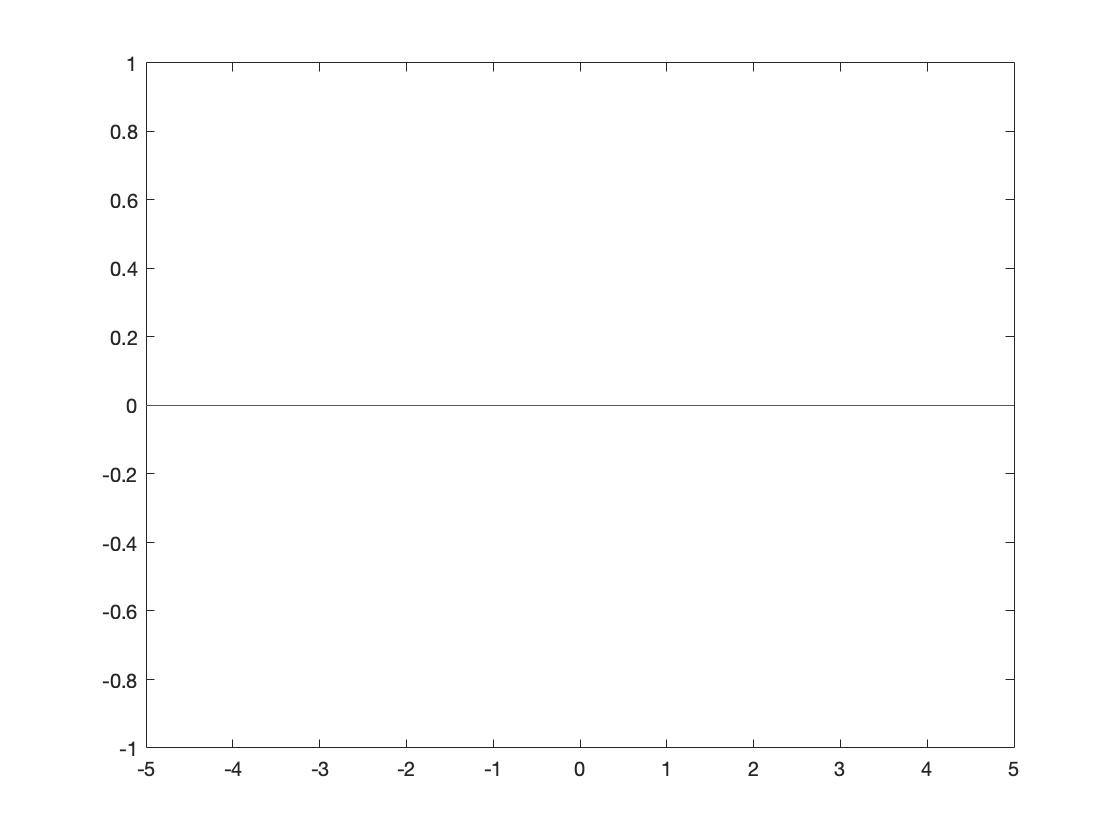

p_0 = 100000; %Pa
c = 1500;
z_0 = -0.05; %m
f = 500000; %Hz
k = (2*pi) / (c/f);
z = -5:0.01:5;
figure(1);
p = [];
for t=1:100
    p = p_0.*exp(z - z_0 - c.*t).*cos(k.*(z - z_0 - c.*t));
    plot(z, p);
    
    drawnow;
    frame = getframe(gcf);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    outfile = 'task4.gif';
%  
    % On the first loop, create the file. In subsequent loops, append.
    if t==1
        imwrite(imind,cm,outfile,'gif','DelayTime',0,'loopcount',inf);
    else
        imwrite(imind,cm,outfile,'gif','DelayTime',0,'writemode','append');
    end
end